clear all
% 
close all


Creating the terrain:

dx=6

dx = 6


signal=[];
A=15

A = 15

%fist terrain profile
%periods=[50,50,50,50,50,50,50,50,50,50,50,50,50,50,50,50,50,50]; %randi([min_period,max_period],[1,3])

%seconf profile to be tested
%periods=[60,40, 70, 40, 60,60,40, 70, 40, 60,60,40, 70, 40, 60, 60, 100,40, 40, 40, 50, 60, 70, 40, 50, 60, 100]

%thrid profile to be tested
%periods=[30,40,20,40,30,14,20,30,40,20,40,30,13,20,30,40,20,40,30,12,20,30,40,20,40,30,13,20,30,40,20,40,30,13,20,30,40,20,40,30,13,20,30,40,20,40,30,20,20]

%fourth profile to be tested       change A for A(p) in line 22
periods=[60,40, 70, 40, 60,60,40, 70, 40, 60,60,40, 70, 40, 60, 60, 100,40, 40, 40, 50, 60, 70, 40, 50, 60, 100]

periods =     60    40    70    40    60    60    40    70    40    60    60    40    70    40    60    60   100    40    40    40    50    60    70    40    50    60   100


A=[15,5, 15, 15,5, 5, 5, 15, 15,15, 15, 5, 15, 15, 5, 5, 15, 15,15, 15, 5, 15, 15, 5, 5, 15, 15,15, 15, 5, 15, 15, 5, 5, 15, 15,15, 15, 5, 15, 15, 5, 5, 15, 15,15, 15, 5, 15, 15, 5, 5, 15, 15]

A =     15     5    15    15     5     5     5    15    15    15    15     5    15    15     5     5    15    15    15    15     5    15    15     5     5    15    15    15    15     5    15    15     5     5    15    15    15    15     5    15    15     5     5    15    15    15    15     5    15    15


for p=1:size(periods,2)
     signal=[signal,step_generator(periods(p), A) ];
end
%Others to test
%signal=[step_generator(8, 1) , step_generator(4, 0.5), step_generator(6, 1), step_generator(3, 0.5), step_generator(6, 1),step_generator(6, 1)];
%signal=[step_generator(5, 0.5) , step_generator(5, 0.5), step_generator(5, 0.5), step_generator(5, 0.5), step_generator(5, 0.5),step_generator(4, 0.5), step_generator(4, 0.5), step_generator(4, 0.5), step_generator(4, 0.5), step_generator(4, 0.5), step_generator(4, 0.5), step_generator(4, 0.5)];
signal

signal =     15    15    15    15    15     0     0     0     0     0     5     5     5     5     0     0     0    15    15    15    15    15    15     0     0     0     0     0     0    15    15    15    15     0     0     0     5     5     5     5     5     0     0     0     0     0     5     5     5     5


d_h_pre=[0];

d_h_post=[0];
for i=2:size(signal,2)-1
    grad=(signal(i)-signal(i-1))/dx;
    d_h_pre=[d_h_pre, grad];
    
    grad=(signal(i+1)-signal(i))/dx;
    d_h_post=[d_h_post, grad];
end

d_h_pre=[d_h_pre,0]

d_h_pre =          0         0         0         0         0   -2.5000         0         0         0         0    0.8333         0         0         0   -0.8333         0         0    2.5000         0         0         0         0         0   -2.5000         0         0         0         0         0    2.5000         0         0         0   -2.5000         0         0    0.8333         0         0         0         0   -0.8333         0         0         0         0    0.8333         0         0         0


d_h_post=[d_h_post,0]

d_h_post =          0         0         0         0   -2.5000         0         0         0         0    0.8333         0         0         0   -0.8333         0         0    2.5000         0         0         0         0         0   -2.5000         0         0         0         0         0    2.5000         0         0         0   -2.5000         0         0    0.8333         0         0         0         0   -0.8333         0         0         0         0    0.8333         0         0         0         0


signal

signal =     15    15    15    15    15     0     0     0     0     0     5     5     5     5     0     0     0    15    15    15    15    15    15     0     0     0     0     0     0    15    15    15    15     0     0     0     5     5     5     5     5     0     0     0     0     0     5     5     5     5


x=1:dx:(size(signal,2)*dx)

x =      1     7    13    19    25    31    37    43    49    55    61    67    73    79    85    91    97   103   109   115   121   127   133   139   145   151   157   163   169   175   181   187   193   199   205   211   217   223   229   235   241   247   253   259   265   271   277   283   289   295


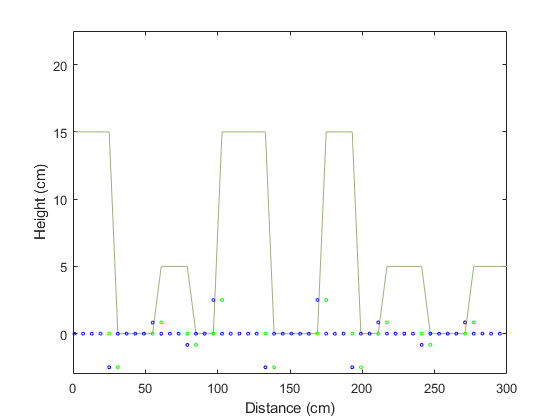

plot(x,signal,"Color", "#9cb27a", 'LineWidth',0.75 )
axis([0 300 -3 15*1.5])
%daspect([2 1 1])
xlabel('Distance (cm)')
ylabel('Height (cm)')
hold on
x=1:dx:(dx*size(signal,2));
scatter(x,d_h_pre,5, 'g')
scatter(x,d_h_post,5, 'b')
% %Generation of the gradient:
hold off

A=[1,0;0,1];
B=[0;1]; 
C=[1;0]

C =      1
     0




nx=2                 % number of states

nx = 2

nu=1                 % number of inputs

nu = 1


% Factors

R=0.75                  % penalty on control action

R = 0.7500

S=0.125                  % penalty on gradient

S = 0.1250

passa_max=28;
max_grad=1;

Hp=8                        %prediction horizon  

Hp = 8

Hs=Hp*5              %simulation horizon

Hs = 40

N=Hp

N = 8



%Symbolic variable declaration
%u = binvar(repmat(nu,1,Hp),repmat(1,1,Hp));
u=sdpvar(repmat(nu,1,N), ones(1,Hp));


l0=0;

r=[30;1]                  %reference for x -- arribe to L

r =     30
     1



Lhist=[];
Uhist=[];
DHhist_pre=[];
DHhist_post=[];

u_min=0;
u_max=1;
 
steps=0;

for t=1:Hs
% Explicit prediction form
    u = sdpvar(repmat(nu,1,N), ones(1,Hp));
    constraints=[];
    objective=0;
    
    
    l=l0;
 
    for k = 1:Hp
        
        l=(l+dx)*(1-u{k}) %(l+1)*(1-u{k})
        %x = A*x + B*u{k} + C*dx %+0.1*rand(3,1);       %COM
        %objective = objective + (r-x)'*Q*(r-x) + u{k}'*R*u{k};
        d_max=2.5
        objective = objective + u{k}'*R*u{k} ;
        k+steps;
        constraints=[constraints, binary(u{k}), l<=passa_max ]; 
        
    end
    
    %, u_min<=u{k}<=u_max
    options = sdpsettings('solver','bnb','bnb.solver','fmincon');
    sol=solvesdp(constraints,objective, options) %quadprog va be tmb
    %sol=solvesdp(constraints,objective)
    uu=value(u{:,1})
%     if uu==0.5
%         uu=1
%     end
    %x0=A*x0+B*uu +C*dx %+ 0.05*rand(3,1)
    
    l0=(l0+dx)*(1-uu);
    steps=steps+1;
    DHhist_pre=[DHhist_pre, d_h_pre(steps)];
    DHhist_post=[DHhist_post, d_h_post(steps)];
    
    Lhist = [Lhist l0];
    Uhist = [Uhist uu];
  
  
end

Linear scalar (real, 1 variable)
Coefficients range: 6 to 6


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 6 to 12


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 6 to 18


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 6 to 24


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 6 to 30


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 6 to 36


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 6 to 42


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 6 to 48


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    2.250E+00    93.17      7.910E-02   1       0.1    -> Found improved solution! 
    2 :    1.500E+00    89.92      7.910E-02   2       0.1    -> Found improved solution! 
    3 :    7.500E-01    67.90      1.430E-01   1       0.2    -> Found improved solution! 
    4 :    7.500E-01    67.90      1.430E-01   0       0.3    Successfully solved  
    5 :    7.500E-01    60.45      1.845E-01   1       0.3    Successfully solved  
    6 :    7.500E-01    60.45      1.845E-01   0       0.4    Successfully solved  
    7 :    7.500E-01    30

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1190
       solvertime: 0.5180
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 12 to 12


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 12 to 18


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 12 to 24


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 12 to 30


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 12 to 36


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 12 to 42


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 12 to 48


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 12 to 54


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    3.000E+00    93.34      1.029E-01   1       0.1    -> Found improved solution! 
    2 :    1.500E+00    87.10      1.029E-01   2       0.1    -> Found improved solution! 
    3 :    1.500E+00    79.85      1.676E-01   3       0.2    Successfully solved  
    4 :    1.500E+00    79.85      1.676E-01   4       0.3    Successfully solved  
    5 :    1.500E+00    75.40      2.100E-01   5       0.3    Successfully solved  
    6 :    1.500E+00    75.40      2.100E-01   4       0.4    Successfully solved  
    7 :    1.500E+00    55.43    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1290
       solvertime: 3.4460
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 18 to 18


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 18 to 24


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 18 to 30


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 18 to 36


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 18 to 42


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 18 to 48


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 18 to 54


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 18 to 60


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    4.293E+00    93.53      1.430E-01   1       0.1    -> Found improved solution! 
    2 :    3.000E+00    90.87      1.430E-01   2       0.1    -> Found improved solution! 
    3 :    3.000E+00    88.06      1.900E-01   3       0.2    Successfully solved  
    4 :    2.250E+00    84.39      1.900E-01   4       0.3    -> Found improved solution! 
    5 :    2.250E+00    77.50      2.848E-01   5       0.4    Successfully solved  
    6 :    2.250E+00    77.50      2.848E-01   6       0.4    Successfully solved  
    7 :    1.500E+00    36

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1220
       solvertime: 1.7450
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 24 to 24


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 24 to 30


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 24 to 36


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 24 to 42


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 24 to 48


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 24 to 54


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 24 to 60


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 24 to 66


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    6.661E+00    94.85      1.757E-01   1       0.1    -> Found improved solution! 
    2 :    4.531E+00    92.52      1.757E-01   2       0.1    -> Found improved solution! 
    3 :    4.531E+00    90.61      2.227E-01   3       0.2    Successfully solved  
    4 :    3.781E+00    88.86      2.227E-01   4       0.3    -> Found improved solution! 
    5 :    3.781E+00    84.46      3.181E-01   5       0.3    Successfully solved  
    6 :    3.781E+00    84.46      3.181E-01   6       0.4    Successfully solved  
    7 :    3.031E+00    59

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1150
       solvertime: 1.8410
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 1

Linear scalar (real, 1 variable)
Coefficients range: 6 to 6


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 6 to 12


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 6 to 18


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 6 to 24


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 6 to 30


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 6 to 36


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 6 to 42


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 6 to 48


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    2.337E+00    94.02      7.151E-02   1       0.1    -> Found improved solution! 
    2 :    2.337E+00    94.02      7.151E-02   2       0.1    Successfully solved  
    3 :    2.337E+00    90.50      1.161E-01   3       0.2    Successfully solved  
    4 :    1.587E+00    86.32      1.161E-01   4       0.3    -> Found improved solution! 
    5 :    7.500E-01    56.39      2.088E-01   1       0.3    -> Found improved solution! 
    6 :    7.500E-01    56.39      2.088E-01   0       0.4    Successfully solved  
    7 :    7.500E-01    44

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1300
       solvertime: 0.7040
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 12 to 12


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 12 to 18


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 12 to 24


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 12 to 30


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 12 to 36


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 12 to 42


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 12 to 48


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 12 to 54


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    3.087E+00    94.01      9.490E-02   1       0.1    -> Found improved solution! 
    2 :    2.337E+00    92.16      9.490E-02   2       0.1    -> Found improved solution! 
    3 :    2.337E+00    88.70      1.395E-01   3       0.2    Successfully solved  
    4 :    1.587E+00    83.79      1.395E-01   4       0.3    -> Found improved solution! 
    5 :    7.500E-01    52.65      2.323E-01   1       0.3    -> Found improved solution! 
    6 :    7.500E-01    52.65      2.323E-01   0       0.4    Successfully solved  
    7 :    7.500E-0

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1180
       solvertime: 0.6980
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 18 to 18


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 18 to 24


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 18 to 30


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 18 to 36


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 18 to 42


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 18 to 48


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 18 to 54


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 18 to 60


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    4.379E+00    94.07      1.333E-01   1       0.1    -> Found improved solution! 
    2 :    3.087E+00    91.69      1.333E-01   2       0.2    -> Found improved solution! 
    3 :    3.087E+00    88.92      1.806E-01   3       0.3    Successfully solved  
    4 :    2.337E+00    85.62      1.806E-01   4       0.3    -> Found improved solution! 
    5 :    1.587E+00    70.19      2.775E-01   5       0.4    -> Found improved solution! 
    6 :    1.587E+00    70.19      2.775E-01   6       0.4    Successfully solved  
    7 :    1.587E+0

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1200
       solvertime: 2.3540
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 24 to 24


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 24 to 30


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 24 to 36


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 24 to 42


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 24 to 48


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 24 to 54


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 24 to 60


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 24 to 66


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    5.216E+00    93.95      1.623E-01   1       0.1    -> Found improved solution! 
    2 :    3.087E+00    89.98      1.623E-01   2       0.2    -> Found improved solution! 
    3 :    3.087E+00    87.22      2.102E-01   3       0.3    Successfully solved  
    4 :    2.337E+00    83.46      2.102E-01   4       0.3    -> Found improved solution! 
    5 :    1.587E+00    67.19      3.110E-01   5       0.4    -> Found improved solution! 
    6 :    1.587E+00    67.19      3.110E-01   6       0.4    Successfully solved  
    7 :    1.587E+0

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1130
       solvertime: 4.1800
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 30 to 30


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 30 to 36


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 30 to 42


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 30 to 48


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 30 to 54


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 30 to 60


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 30 to 66


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 30 to 72


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    7.259E+00    80.26      7.945E-01   1       0.1    -> Found improved solution! 
    2 :    7.259E+00    80.26      7.945E-01   2       0.2    Successfully solved  
    3 :    2.337E+00    47.71      8.269E-01   3       0.2    -> Found improved solution! 
    4 :    2.337E+00    47.71      8.269E-01   4       0.3    Successfully solved  
    5 :    2.337E+00    44.51      8.971E-01   5       0.3    Successfully solved  
    6 :    1.500E+00    25.14      8.971E-01   0       0.4    -> Found improved solution! 
    7 :    1.500E+00    21

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1190
       solvertime: 2.1560
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 1

Linear scalar (real, 1 variable)
Coefficients range: 6 to 6


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 6 to 12


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 6 to 18


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 6 to 24


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 6 to 30


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 6 to 36


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 6 to 42


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 6 to 48


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    2.337E+00    91.74      1.002E-01   1       0.1    -> Found improved solution! 
    2 :    2.337E+00    91.74      1.002E-01   2       0.1    Successfully solved  
    3 :    2.337E+00    86.55      1.680E-01   3       0.2    Successfully solved  
    4 :    2.337E+00    86.55      1.680E-01   4       0.3    Successfully solved  
    5 :    7.500E-01    43.29      2.965E-01   1       0.3    -> Found improved solution! 
    6 :    7.500E-01    43.29      2.965E-01   0       0.4    Successfully solved  
    7 :    7.500E-01    33.02    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1190
       solvertime: 0.6730
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 12 to 12


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 12 to 18


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 12 to 24


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 12 to 30


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 12 to 36


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 12 to 42


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 12 to 48


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 12 to 54


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    3.868E+00    92.60      1.481E-01   1       0.1    -> Found improved solution! 
    2 :    3.868E+00    92.60      1.481E-01   2       0.1    Successfully solved  
    3 :    3.868E+00    89.39      2.162E-01   3       0.2    Successfully solved  
    4 :    3.868E+00    89.39      2.162E-01   4       0.2    Successfully solved  
    5 :    2.043E+00    71.05      3.453E-01   5       0.3    -> Found improved solution! 
    6 :    2.043E+00    71.05      3.453E-01   6       0.4    Successfully solved  
    7 :    1.293E+00    50.32    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1190
       solvertime: 3.4910
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 18 to 18


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 18 to 24


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 18 to 30


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 18 to 36


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 18 to 42


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 18 to 48


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 18 to 54


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 18 to 60


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    4.618E+00    92.76      1.730E-01   1       0.1    -> Found improved solution! 
    2 :    4.618E+00    92.76      1.730E-01   2       0.1    Successfully solved  
    3 :    4.618E+00    89.99      2.429E-01   3       0.2    Successfully solved  
    4 :    4.618E+00    89.99      2.429E-01   4       0.3    Successfully solved  
    5 :    4.618E+00    84.89      3.769E-01   5       0.3    Successfully solved  
    6 :    4.618E+00    84.89      3.769E-01   6       0.4    Successfully solved  
    7 :    4.618E+00    81.72      4.642

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1200
       solvertime: 2.1750
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 24 to 24


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 24 to 30


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 24 to 36


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 24 to 42


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 24 to 48


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 24 to 54


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 24 to 60


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 24 to 66


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    5.368E+00    92.78      2.007E-01   1       0.1    -> Found improved solution! 
    2 :    5.368E+00    92.78      2.007E-01   2       0.1    Successfully solved  
    3 :    5.368E+00    90.18      2.767E-01   3       0.2    Successfully solved  
    4 :    5.368E+00    90.18      2.767E-01   4       0.2    Successfully solved  
    5 :    5.368E+00    85.19      4.287E-01   5       0.3    Successfully solved  
    6 :    5.368E+00    85.19      4.287E-01   6       0.4    Successfully solved  
    7 :    5.368E+00    81.50      5.468

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1460
       solvertime: 3.4810
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 1

Linear scalar (real, 1 variable)
Coefficients range: 6 to 6


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 6 to 12


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 6 to 18


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 6 to 24


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 6 to 30


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 6 to 36


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 6 to 42


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 6 to 48


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    1.229E+01    98.84      7.120E-02   1       0.1    -> Found improved solution! 
    2 :    1.229E+01    98.84      7.120E-02   2       0.1    Successfully solved  
    3 :    1.229E+01    98.18      1.124E-01   3       0.2    Successfully solved  
    4 :    1.229E+01    98.18      1.124E-01   4       0.3    Successfully solved  
    5 :    3.031E+00    87.87      1.952E-01   5       0.4    -> Found improved solution! 
    6 :    3.031E+00    87.87      1.952E-01   6       0.4    Successfully solved  
    7 :    1.531E+00    45.89    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1390
       solvertime: 2.4250
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 12 to 12


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 12 to 18


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 12 to 24


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 12 to 30


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 12 to 36


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 12 to 42


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 12 to 48


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 12 to 54


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    1.175E+01    98.39      9.471E-02   1       0.1    -> Found improved solution! 
    2 :    1.175E+01    98.39      9.471E-02   2       0.1    Successfully solved  
    3 :    1.175E+01    97.70      1.360E-01   3       0.2    Successfully solved  
    4 :    1.175E+01    97.70      1.360E-01   4       0.3    Successfully solved  
    5 :    3.781E+00    89.02      2.191E-01   5       0.4    -> Found improved solution! 
    6 :    3.781E+00    89.02      2.191E-01   6       0.4    Successfully solved  
    7 :    1.531E+00    44.13    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1250
       solvertime: 1.8870
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 18 to 18


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 18 to 24


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 18 to 30


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 18 to 36


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 18 to 42


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 18 to 48


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 18 to 54


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 18 to 60


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    1.655E+01    98.12      1.563E-01   1       0.1    -> Found improved solution! 
    2 :    1.655E+01    98.12      1.563E-01   2       0.2    Successfully solved  
    3 :    1.655E+01    97.22      2.330E-01   3       0.3    Successfully solved  
    4 :    1.655E+01    97.22      2.330E-01   4       0.3    Successfully solved  
    5 :    2.250E+00    72.72      3.549E-01   5       0.4    -> Found improved solution! 
    6 :    2.250E+00    72.72      3.549E-01   6       0.5    Successfully solved  
    7 :    2.250E+00    62.16    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1170
       solvertime: 2.3300
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 1

Linear scalar (real, 1 variable)
Coefficients range: 6 to 6


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 6 to 12


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 6 to 18


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 6 to 24


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 6 to 30


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 6 to 36


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 6 to 42


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 6 to 48


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    3.781E+00    94.43      1.078E-01   1       0.1    -> Found improved solution! 
    2 :    3.781E+00    94.43      1.078E-01   2       0.1    Successfully solved  
    3 :    7.500E-01    66.75      1.491E-01   1       0.2    -> Found improved solution! 
    4 :    7.500E-01    66.75      1.491E-01   0       0.2    Successfully solved  
    5 :    7.500E-01    54.09      2.231E-01   1       0.3    Successfully solved  
    6 :    7.500E-01    54.09      2.231E-01   0       0.4    Successfully solved  
    7 :    7.500E-01    35.99    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1330
       solvertime: 0.5110
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 12 to 12


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 12 to 18


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 12 to 24


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 12 to 30


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 12 to 36


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 12 to 42


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 12 to 48


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 12 to 54


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    4.531E+00    94.35      1.312E-01   1       0.1    -> Found improved solution! 
    2 :    4.531E+00    94.35      1.312E-01   2       0.1    Successfully solved  
    3 :    7.500E-01    62.52      1.726E-01   1       0.2    -> Found improved solution! 
    4 :    7.500E-01    62.52      1.726E-01   0       0.2    Successfully solved  
    5 :    7.500E-01    50.44      2.467E-01   1       0.3    Successfully solved  
    6 :    7.500E-01    50.44      2.467E-01   0       0.4    Successfully solved  
    7 :    7.500E-01    33.09    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1250
       solvertime: 0.4740
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 18 to 18


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 18 to 24


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 18 to 30


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 18 to 36


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 18 to 42


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 18 to 48


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 18 to 54


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 18 to 60


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    5.281E+00    94.26      1.555E-01   1       0.1    -> Found improved solution! 
    2 :    5.281E+00    94.26      1.555E-01   2       0.1    Successfully solved  
    3 :    5.281E+00    92.76      1.978E-01   3       0.2    Successfully solved  
    4 :    5.281E+00    92.76      1.978E-01   4       0.3    Successfully solved  
    5 :    4.531E+00    88.55      2.746E-01   5       0.3    -> Found improved solution! 
    6 :    2.250E+00    78.21      2.746E-01   6       0.4    -> Found improved solution! 
    7 :    2.250E+00    69

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1310
       solvertime: 3.7280
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 24 to 24


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 24 to 30


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 24 to 36


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 24 to 42


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 24 to 48


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 24 to 54


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 24 to 60


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 24 to 66


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    6.031E+00    94.07      1.838E-01   1       0.1    -> Found improved solution! 
    2 :    6.031E+00    94.07      1.838E-01   2       0.1    Successfully solved  
    3 :    5.281E+00    91.56      2.323E-01   3       0.2    -> Found improved solution! 
    4 :    5.281E+00    91.56      2.323E-01   4       0.3    Successfully solved  
    5 :    4.531E+00    86.50      3.276E-01   5       0.3    -> Found improved solution! 
    6 :    3.000E+00    80.29      3.276E-01   6       0.4    -> Found improved solution! 
    7 :    3.000E+0

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1180
       solvertime: 3.1170
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 30 to 30


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 30 to 36


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 30 to 42


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 30 to 48


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 30 to 54


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 30 to 60


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 30 to 66


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 30 to 72


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    1.166E+01    87.28      7.920E-01   1       0.1    -> Found improved solution! 
    2 :    1.166E+01    87.28      7.920E-01   2       0.1    Successfully solved  
    3 :    3.000E+00    57.12      8.184E-01   3       0.2    -> Found improved solution! 
    4 :    3.000E+00    57.12      8.184E-01   4       0.3    Successfully solved  
    5 :    1.500E+00    26.49      8.715E-01   1       0.3    -> Found improved solution! 
    6 :    1.500E+00    26.49      8.715E-01   0       0.4    Successfully solved  
    7 :    1.500E+00    20

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1240
       solvertime: 0.4950
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 1

Linear scalar (real, 1 variable)
Coefficients range: 6 to 6


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 6 to 12


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 6 to 18


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 6 to 24


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 6 to 30


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 6 to 36


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 6 to 42


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 6 to 48


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    2.250E+00    91.85      9.509E-02   1       0.1    -> Found improved solution! 
    2 :    2.250E+00    91.85      9.509E-02   2       0.1    Successfully solved  
    3 :    1.500E+00    81.72      1.505E-01   3       0.2    -> Found improved solution! 
    4 :    1.500E+00    81.72      1.505E-01   4       0.3    Successfully solved  
    5 :    7.500E-01    50.42      2.469E-01   1       0.3    -> Found improved solution! 
    6 :    7.500E-01    50.42      2.469E-01   0       0.4    Successfully solved  
    7 :    7.500E-01    29

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1420
       solvertime: 0.5250
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 12 to 12


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 12 to 18


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 12 to 24


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 12 to 30


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 12 to 36


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 12 to 42


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 12 to 48


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 12 to 54


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    4.531E+00    93.86      1.430E-01   1       0.1    -> Found improved solution! 
    2 :    4.531E+00    93.86      1.430E-01   2       0.1    Successfully solved  
    3 :    1.500E+00    76.54      1.989E-01   3       0.2    -> Found improved solution! 
    4 :    1.500E+00    76.54      1.989E-01   4       0.3    Successfully solved  
    5 :    7.500E-01    43.35      2.961E-01   1       0.3    -> Found improved solution! 
    6 :    7.500E-01    43.35      2.961E-01   0       0.4    Successfully solved  
    7 :    7.500E-01    24

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1180
       solvertime: 0.5290
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 18 to 18


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 18 to 24


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 18 to 30


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 18 to 36


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 18 to 42


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 18 to 48


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 18 to 54


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 18 to 60


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    5.281E+00    93.87      1.666E-01   1       0.1    -> Found improved solution! 
    2 :    5.281E+00    93.87      1.666E-01   2       0.1    Successfully solved  
    3 :    1.500E+00    74.10      2.227E-01   3       0.2    -> Found improved solution! 
    4 :    1.500E+00    74.10      2.227E-01   4       0.3    Successfully solved  
    5 :    1.500E+00    64.78      3.203E-01   5       0.3    Successfully solved  
    6 :    1.500E+00    64.78      3.203E-01   6       0.4    Successfully solved  
    7 :    1.500E+00    51.50    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1200
       solvertime: 2.0860
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 24 to 24


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 24 to 30


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 24 to 36


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 24 to 42


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 24 to 48


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 24 to 54


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 24 to 60


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 24 to 66


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    6.031E+00    93.82      1.918E-01   1       0.1    -> Found improved solution! 
    2 :    6.031E+00    93.82      1.918E-01   2       0.1    Successfully solved  
    3 :    5.281E+00    90.95      2.497E-01   3       0.2    -> Found improved solution! 
    4 :    5.281E+00    90.95      2.497E-01   4       0.3    Successfully solved  
    5 :    4.531E+00    85.60      3.511E-01   5       0.3    -> Found improved solution! 
    6 :    2.250E+00    72.98      3.511E-01   6       0.4    -> Found improved solution! 
    7 :    2.250E+0

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1210
       solvertime: 3.6890
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 30 to 30


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 30 to 36


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 30 to 42


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 30 to 48


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 30 to 54


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 30 to 60


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 30 to 66


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 30 to 72


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    2.250E+00    46.64      8.185E-01   1       0.1    -> Found improved solution! 
    2 :    2.250E+00    46.64      8.185E-01   2       0.1    Successfully solved  
    3 :    1.500E+00    26.51      8.711E-01   1       0.2    -> Found improved solution! 
    4 :    1.500E+00    26.51      8.711E-01   0       0.2    Successfully solved  
    5 :    1.500E+00    18.31      1.036E+00   1       0.3    Successfully solved  
    6 :    1.500E+00    18.31      1.036E+00   0       0.3    Successfully solved  
    7 :    1.500E+00    10.52    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1260
       solvertime: 0.4320
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 1

Linear scalar (real, 1 variable)
Coefficients range: 6 to 6


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 6 to 12


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 6 to 18


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 6 to 24


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 6 to 30


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 6 to 36


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 6 to 42


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 6 to 48


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    3.031E+00    92.62      1.157E-01   1       0.1    -> Found improved solution! 
    2 :    3.031E+00    92.62      1.157E-01   2       0.1    Successfully solved  
    3 :    7.500E-01    63.19      1.688E-01   1       0.2    -> Found improved solution! 
    4 :    7.500E-01    63.19      1.688E-01   0       0.3    Successfully solved  
    5 :    7.500E-01    38.44      3.332E-01   1       0.3    Successfully solved  
    6 :    7.500E-01    38.44      3.332E-01   0       0.3    Successfully solved  
    7 :    7.500E-01    18.84    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1180
       solvertime: 0.4610
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 12 to 12


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 12 to 18


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 12 to 24


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 12 to 30


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 12 to 36


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 12 to 42


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 12 to 48


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 12 to 54


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    3.781E+00    92.85      1.396E-01   1       0.1    -> Found improved solution! 
    2 :    3.781E+00    92.85      1.396E-01   2       0.2    Successfully solved  
    3 :    7.500E-01    58.94      1.934E-01   1       0.2    -> Found improved solution! 
    4 :    7.500E-01    58.94      1.934E-01   0       0.3    Successfully solved  
    5 :    7.500E-01    34.79      3.626E-01   1       0.3    Successfully solved  
    6 :    7.500E-01    34.79      3.626E-01   0       0.3    Successfully solved  
    7 :    7.500E-01    15.61    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1210
       solvertime: 0.4600
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 18 to 18


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 18 to 24


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 18 to 30


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 18 to 36


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 18 to 42


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 18 to 48


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 18 to 54


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 18 to 60


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    5.074E+00    93.13      1.800E-01   1       0.1    -> Found improved solution! 
    2 :    5.074E+00    93.13      1.800E-01   2       0.1    Successfully solved  
    3 :    1.500E+00    72.64      2.373E-01   3       0.2    -> Found improved solution! 
    4 :    1.500E+00    72.64      2.373E-01   4       0.3    Successfully solved  
    5 :    1.500E+00    54.59      4.403E-01   5       0.3    Successfully solved  
    6 :    1.500E+00    54.59      4.403E-01   4       0.3    Successfully solved  
    7 :    1.500E+00    33.17    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1200
       solvertime: 1.5770
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 24 to 24


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 24 to 30


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 24 to 36


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 24 to 42


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 24 to 48


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 24 to 54


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 24 to 60


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 24 to 66


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    5.911E+00    93.23      2.068E-01   1       0.1    -> Found improved solution! 
    2 :    5.911E+00    93.23      2.068E-01   2       0.1    Successfully solved  
    3 :    1.500E+00    69.91      2.652E-01   3       0.2    -> Found improved solution! 
    4 :    1.500E+00    69.91      2.652E-01   4       0.2    Successfully solved  
    5 :    1.500E+00    51.58      4.789E-01   5       0.3    Successfully solved  
    6 :    1.500E+00    51.58      4.789E-01   4       0.3    Successfully solved  
    7 :    1.500E+00    33.04    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1180
       solvertime: 2.7140
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 30 to 30


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 30 to 36


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 30 to 42


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 30 to 48


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 30 to 54


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 30 to 60


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 30 to 66


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 30 to 72


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    1.229E+01    87.82      7.964E-01   1       0.1    -> Found improved solution! 
    2 :    1.229E+01    87.82      7.964E-01   2       0.1    Successfully solved  
    3 :    3.629E+00    62.69      8.320E-01   3       0.2    -> Found improved solution! 
    4 :    3.629E+00    62.69      8.320E-01   4       0.3    Successfully solved  
    5 :    1.500E+00    24.27      9.139E-01   1       0.3    -> Found improved solution! 
    6 :    1.500E+00    24.27      9.139E-01   0       0.4    Successfully solved  
    7 :    1.500E+00    20

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1210
       solvertime: 0.4860
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 1

Linear scalar (real, 1 variable)
Coefficients range: 6 to 6


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 6 to 12


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 6 to 18


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 6 to 24


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 6 to 30


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 6 to 36


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 6 to 42


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 6 to 48


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    1.229E+01    98.86      6.980E-02   1       0.1    -> Found improved solution! 
    2 :    1.229E+01    98.86      6.980E-02   2       0.1    Successfully solved  
    3 :    2.337E+00    90.96      1.101E-01   3       0.2    -> Found improved solution! 
    4 :    2.337E+00    90.96      1.101E-01   4       0.3    Successfully solved  
    5 :    2.337E+00    84.42      1.969E-01   5       0.4    Successfully solved  
    6 :    2.337E+00    84.42      1.969E-01   6       0.4    Successfully solved  
    7 :    7.500E-01    28.26    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1310
       solvertime: 0.7570
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 12 to 12


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 12 to 18


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 12 to 24


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 12 to 30


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 12 to 36


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 12 to 42


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 12 to 48


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 12 to 54


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    1.229E+01    98.48      9.342E-02   1       0.1    -> Found improved solution! 
    2 :    1.229E+01    98.48      9.342E-02   2       0.1    Successfully solved  
    3 :    3.087E+00    91.65      1.339E-01   3       0.2    -> Found improved solution! 
    4 :    3.087E+00    91.65      1.339E-01   4       0.3    Successfully solved  
    5 :    3.087E+00    86.59      2.214E-01   5       0.4    Successfully solved  
    6 :    3.087E+00    86.59      2.214E-01   6       0.4    Successfully solved  
    7 :    2.043E+00    64.17    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1270
       solvertime: 1.8660
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 18 to 18


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 18 to 24


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 18 to 30


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 18 to 36


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 18 to 42


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 18 to 48


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 18 to 54


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 18 to 60


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    7.953E+00    96.74      1.315E-01   1       0.1    -> Found improved solution! 
    2 :    7.953E+00    96.74      1.315E-01   2       0.1    Successfully solved  
    3 :    7.953E+00    95.62      1.775E-01   3       0.2    Successfully solved  
    4 :    7.953E+00    95.62      1.775E-01   4       0.3    Successfully solved  
    5 :    4.922E+00    89.92      2.608E-01   5       0.4    -> Found improved solution! 
    6 :    4.922E+00    89.92      2.608E-01   6       0.4    Successfully solved  
    7 :    4.172E+00    81.23    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1310
       solvertime: 3.9220
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 24 to 24


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 24 to 30


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 24 to 36


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 24 to 42


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 24 to 48


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 24 to 54


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 24 to 60


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 24 to 66


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    7.259E+00    95.71      1.588E-01   1       0.1    -> Found improved solution! 
    2 :    7.259E+00    95.71      1.588E-01   2       0.1    Successfully solved  
    3 :    7.259E+00    94.49      2.052E-01   3       0.2    Successfully solved  
    4 :    7.259E+00    94.49      2.052E-01   4       0.3    Successfully solved  
    5 :    5.759E+00    90.40      2.900E-01   5       0.3    -> Found improved solution! 
    6 :    5.759E+00    90.40      2.900E-01   6       0.4    Successfully solved  
    7 :    5.009E+00    83.07    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1230
       solvertime: 4.6200
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 1

Linear scalar (real, 1 variable)
Coefficients range: 6 to 6


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 6 to 12


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 6 to 18


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 6 to 24


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 6 to 30


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 6 to 36


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 6 to 42


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 6 to 48


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    2.337E+00    94.07      7.094E-02   1       0.1    -> Found improved solution! 
    2 :    2.337E+00    94.07      7.094E-02   2       0.2    Successfully solved  
    3 :    2.337E+00    90.58      1.150E-01   3       0.2    Successfully solved  
    4 :    1.587E+00    86.43      1.150E-01   4       0.3    -> Found improved solution! 
    5 :    7.500E-01    56.79      2.063E-01   1       0.4    -> Found improved solution! 
    6 :    7.500E-01    56.79      2.063E-01   0       0.4    Successfully solved  
    7 :    7.500E-01    44

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1380
       solvertime: 0.7240
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 12 to 12


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 12 to 18


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 12 to 24


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 12 to 30


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 12 to 36


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 12 to 42


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 12 to 48


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 12 to 54


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    3.087E+00    94.03      9.445E-02   1       0.1    -> Found improved solution! 
    2 :    2.337E+00    92.19      9.445E-02   2       0.1    -> Found improved solution! 
    3 :    2.337E+00    88.76      1.387E-01   3       0.2    Successfully solved  
    4 :    1.587E+00    83.88      1.387E-01   4       0.3    -> Found improved solution! 
    5 :    7.500E-01    52.96      2.303E-01   1       0.3    -> Found improved solution! 
    6 :    7.500E-01    52.96      2.303E-01   0       0.4    Successfully solved  
    7 :    7.500E-0

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1330
       solvertime: 0.6580
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 18 to 18


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 18 to 24


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 18 to 30


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 18 to 36


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 18 to 42


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 18 to 48


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 18 to 54


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 18 to 60


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    3.837E+00    93.97      1.188E-01   1       0.1    -> Found improved solution! 
    2 :    2.337E+00    90.29      1.188E-01   2       0.1    -> Found improved solution! 
    3 :    2.337E+00    86.86      1.638E-01   3       0.2    Successfully solved  
    4 :    1.587E+00    81.24      1.638E-01   4       0.3    -> Found improved solution! 
    5 :    1.587E+00    71.99      2.580E-01   5       0.3    Successfully solved  
    6 :    1.587E+00    71.99      2.580E-01   6       0.4    Successfully solved  
    7 :    1.587E+00    64

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1380
       solvertime: 2.6090
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 24 to 24


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 24 to 30


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 24 to 36


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 24 to 42


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 24 to 48


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 24 to 54


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 24 to 60


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 24 to 66


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    5.129E+00    93.95      1.596E-01   1       0.1    -> Found improved solution! 
    2 :    3.837E+00    91.99      1.596E-01   2       0.1    -> Found improved solution! 
    3 :    3.837E+00    89.76      2.066E-01   3       0.2    Successfully solved  
    4 :    3.087E+00    87.43      2.066E-01   4       0.3    -> Found improved solution! 
    5 :    3.087E+00    82.39      2.976E-01   5       0.4    Successfully solved  
    6 :    2.337E+00    77.37      2.976E-01   6       0.5    -> Found improved solution! 
    7 :    2.337E+0

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1260
       solvertime: 4.0120
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 0

Linear scalar (real, 1 variable)
Coefficients range: 30 to 30


d_max = 2.5000

Bilinear scalar (real, 2 variables)
Coefficients range: 30 to 36


d_max = 2.5000

Polynomial scalar (real, 3 variables)
Coefficients range: 30 to 42


d_max = 2.5000

Polynomial scalar (real, 4 variables)
Coefficients range: 30 to 48


d_max = 2.5000

Polynomial scalar (real, 5 variables)
Coefficients range: 30 to 54


d_max = 2.5000

Polynomial scalar (real, 6 variables)
Coefficients range: 30 to 60


d_max = 2.5000

Polynomial scalar (real, 7 variables)
Coefficients range: 30 to 66


d_max = 2.5000

Polynomial scalar (real, 8 variables)
Coefficients range: 30 to 72


d_max = 2.5000

* Starting YALMIP integer branch & bound.
* Lower solver   : fmincon-standard
* Upper solver   : rounder
* Max time       : 3600
* Max iterations : Inf
 
that the branching process is not guaranteed to find a
globally optimal solution, since the lower bound can be
invalid. Hence, do not trust the bound or the gap...
 Node       Upper       Gap(%)     Lower     Open   Elapsed time
    1 :    2.337E+00    49.09      7.976E-01   1       0.1    -> Found improved solution! 
    2 :    2.337E+00    49.09      7.976E-01   2       0.1    Successfully solved  
    3 :    1.500E+00    28.70      8.307E-01   1       0.2    -> Found improved solution! 
    4 :    1.500E+00    28.70      8.307E-01   0       0.2    Successfully solved  
    5 :    1.500E+00    26.75      8.667E-01   1       0.3    Successfully solved  
    6 :    1.500E+00    26.75      8.667E-01   0       0.4    Successfully solved  
    7 :    1.500E+00    21.76    

sol = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.10.0.1602886 (R2021a)'
       yalmiptime: 0.1230
       solvertime: 2.1330
             info: 'Successfully solved (BNB)'
          problem: 0


uu = 1

%plot



passos=[]


passos =

     []



prev=0

prev = 0

z_pas=8

z_pas = 8


for i=1:length(Uhist)
    if Uhist(i)==1
        i;
        mig=fix((i-prev)/2+prev);
        passos=[passos;prev*dx, mig*dx, i*dx ];
        prev=i;
    end
end
passos

passos =      0    12    24
    24    36    54
    54    66    78
    78    84    96
    96   108   126
   126   138   156
   156   168   186
   186   198   210
   210   222   240


passos=passos

passos =      0    12    24
    24    36    54
    54    66    78
    78    84    96
    96   108   126
   126   138   156
   156   168   186
   186   198   210
   210   222   240


%x_signal=1:dx:length(signal)*dx
%signal
%plot(x_signal ,signal,'Color', "#9cb27a", 'LineWidth',0.75 )
%signal to plot
hpy=[]


hpy =

     []



count=1

count = 1

prev=signal(1)

prev = 15

for i =1:length(signal)
    hpy=[hpy, signal(i)*ones(1,6)]; 
end
x_signal=1:1:length(hpy)

x_signal =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


hpy

hpy =     15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15    15     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


plot(x_signal ,hpy,'Color', "#9cb27a", 'LineWidth',0.75 )
axis([0 Hs*dx+5 0 25])
hold on
colors=["#ffc9de ","#fdd97c " , "#b2e4f0 ", "#d6b2f0 "];
color=1;
%primer pas
syms a b c
x_p = [passos(1,1),passos(1,2),passos(1,3)]

x_p =      0    12    24


h_max=max(signal(1), signal(fix(passos(1,3))))

h_max = 15

if h_max ==0
    h_max=z_pas;
end
y_p = [signal(fix(1)), h_max*1.5, signal(fix(passos(1,3))/6)]

y_p =    15.0000   22.5000   15.0000


eqn = y_p == a*x_p.^2+b*x_p+c;

sol = solve(eqn,[a b c]);
a_s=double(sol.a);
b_s=double(sol.b);
c_s=double(sol.c);

x_pp=passos(1,1):dx:passos(1,3)

x_pp =      0     6    12    18    24


y_pp=x_pp.^2*a_s+x_pp.*b_s+c_s

y_pp =    15.0000   20.6250   22.5000   20.6250   15.0000


colors(color)

ans = "#ffc9de "

plot(x_pp,y_pp, 'Color', colors(color), 'LineWidth',1)
title("Simulation with variable periods and gradients")
xlabel('Distance (cm)')
ylabel('Height (cm)')
color=color+1

color = 2


for i=2:length(passos)
    syms a b c
    x_p = [passos(i,1),passos(i,2),passos(i,3)]
    h_max=max(signal(fix(passos(i,1)/dx)), signal(fix(passos(i,3)/dx)))
    if h_max == 0
        h_max=z_pas;
    end
    y_p = [signal(fix(passos(i,1)/dx)), h_max*1.3, signal(fix(passos(i,3)/dx))]
    eqn = y_p == a*x_p.^2+b*x_p+c;
 
    sol = solve(eqn,[a b c]);
    a_s=double(sol.a);
    b_s=double(sol.b);
    c_s=double(sol.c);

    x_pp=passos(i,1):dx:passos(i,3);
    y_pp=x_pp.^2*a_s+x_pp.*b_s+c_s;
    colors(color)
    plot(x_pp,y_pp, 'Color', colors(color), 'LineWidth',1)
    color=color+1
    if color== length(colors)
        color=1;
    end
    
end

x_p =     24    36    54


h_max = 15

y_p =    15.0000   19.5000         0


ans = "#fdd97c "

color = 3

x_p =     54    66    78


h_max = 5

y_p =          0    6.5000    5.0000


ans = "#b2e4f0 "

color = 4

x_p =     78    84    96


h_max = 5

y_p =     5.0000    6.5000         0


ans = "#ffc9de "

color = 2

x_p =     96   108   126


h_max = 15

y_p =          0   19.5000   15.0000


ans = "#fdd97c "

color = 3

x_p =    126   138   156


h_max = 15

y_p =    15.0000   19.5000         0


ans = "#b2e4f0 "

color = 4

x_p =    156   168   186


h_max = 15

y_p =          0   19.5000   15.0000


ans = "#ffc9de "

color = 2

x_p =    186   198   210


h_max = 15

y_p =    15.0000   19.5000         0


ans = "#fdd97c "

color = 3

x_p =    210   222   240


h_max = 5

y_p =          0    6.5000    5.0000


ans = "#b2e4f0 "

color = 4

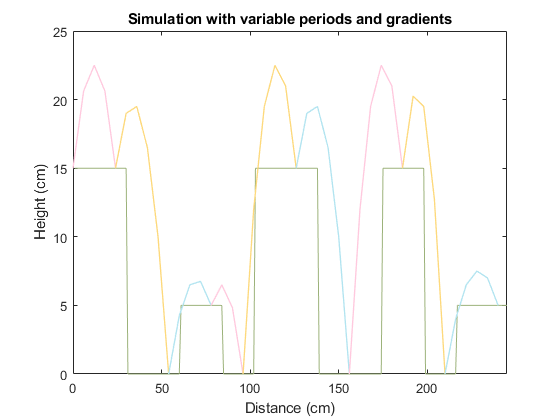



hold off